## SECTION 1: Jump/Flight Escape Reflex Response in the Fly

When a resting fly is threatened by something in the surrounding environment, it will leap into the air and fly away. This is known as the JUMP/FLIGHT ESCAPE REFLEX. 

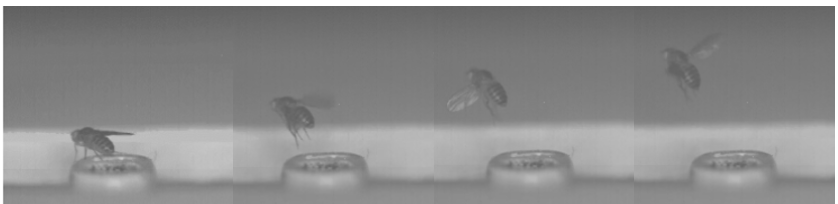

The escape reflex circuit in the fly's brain solves a binary classification problem: discriminating DANGER (class 1) from SAFETY (class 0). If the fly is in danger, then the escape reflex is triggered. If the fly is safe, the reflex is not triggered. 

How can the fly tell if it is in danger? Danger is typically signalled by a sudden change in the sensory environment: a loud noise, a gust of air, the sudden appearance of a predator in the visual field. Small or gradual changes in the sensory environment do not signal danger, whereas large or sudden changes do. So, discriminating danger is a matter of setting a linear threshold to decide how much change in the environment is "too much" change for the fly to feel safe. This is a canonical linear classification problem:    

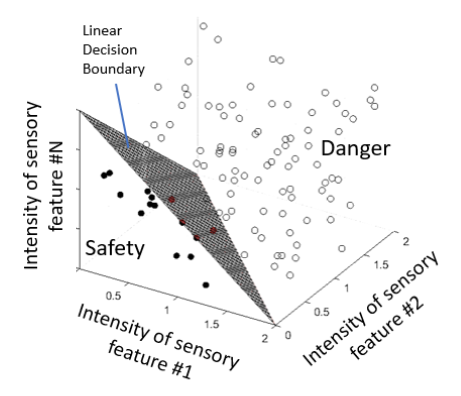

A fly may be in danger if it sees an approaching visual stimulus that is growing larger in the visual field. This is referred to as a LOOMING STIMULUS. If you run the code below, you will see a short video of a person's hand coming down to swat a fly from the fly's point of view. This is an example of a dangerous looming stimulus that might trigger an escape response from a fly.

To watch the video, click anywhere inside of the code block below and then click the 'Run Section' button in the menu bar. Make sure that you click 'Run Section' and not 'Run.'

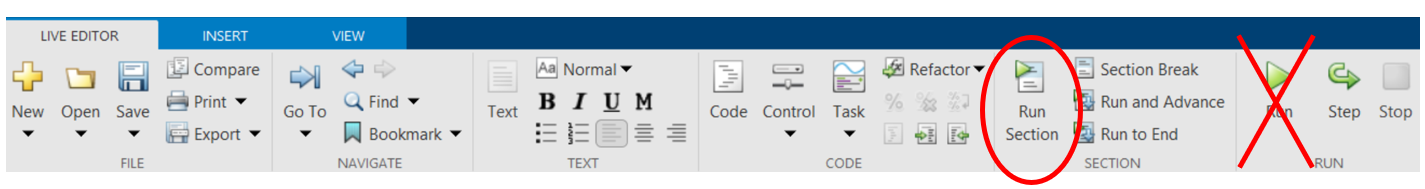

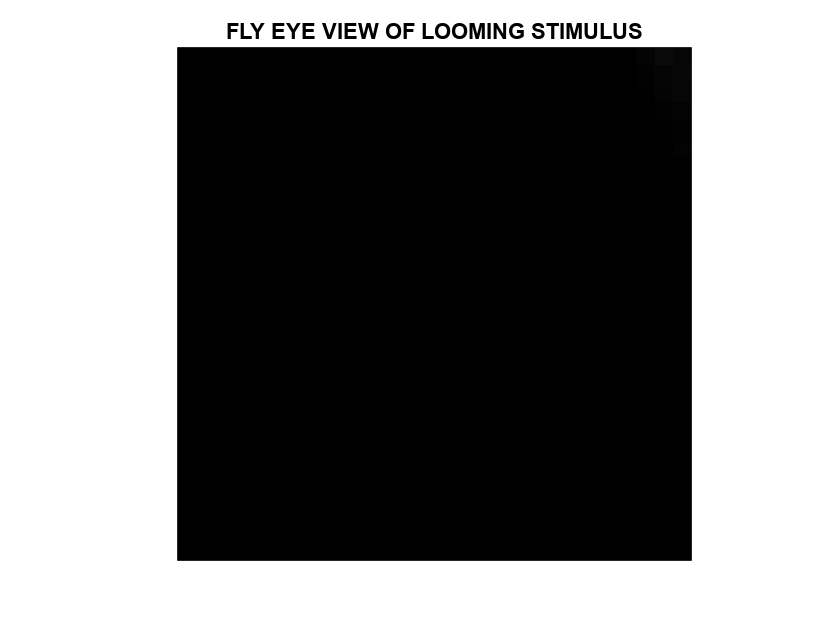

clear all; % clear all workspace variables

% set working directory to 'userpath' if it exists
if exist('userpath')
    workingfolder=['C:\Users\ericy\OneDrive\Desktop\UCLA College stuffs\Senior Class\Winter\PSYCH 119D\MATLAB'];
else % otherwise use current directory
    workingfolder=pwd;
end

% load video and user data 
load([workingfolder '/flyswat']); % swatting hand
load([workingfolder '/flyby']); % passing hand

clf; % clear the display area
subplot(1,1,1); % subplot fills the whole display area (for video controls) 
hImg = image(255-squeeze(vid(:,:,1))); % plot first frame (hImg = handle to image object)
colormap gray; % images to be plotted as grayscale
axis square; % image display to be a perfect square
set(gca,'XTick','','YTick',''); % no axis labels
title('FLY EYE VIEW OF LOOMING STIMULUS');
for f=2:25 % loop through remaining frames and plot them
    hImg.CData = 255-squeeze(vid(:,:,f)); % copy next frame into image data 
    drawnow limitrate; % render image before the next loop iteration
    pause(.1); % pause to slow down the frame rate
end

## SECTION 2: Fly compound eye

A fly sees the world through is COMPOUND EYES.

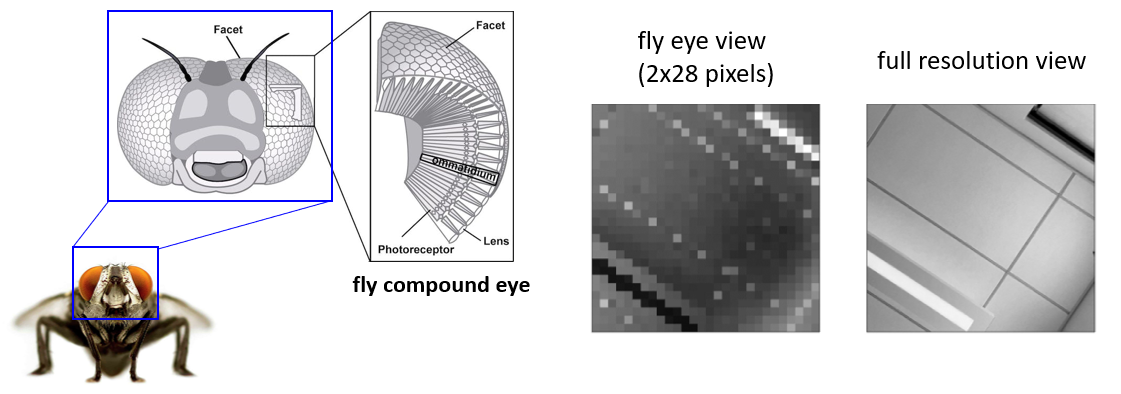

The fly’s compound eye is like a tiny TV screen: it is made of faceted light detectors called *ommatidia*, which function like the individual pixels that form an image on a computer screen. The video of the swatting hand contains 25 frames, and each frame contains 28x28 pixels (each representing one photoreceptor in the fly's eye). To see all 25 frames in the sequence, click in the code window below and hit "Run Section." 

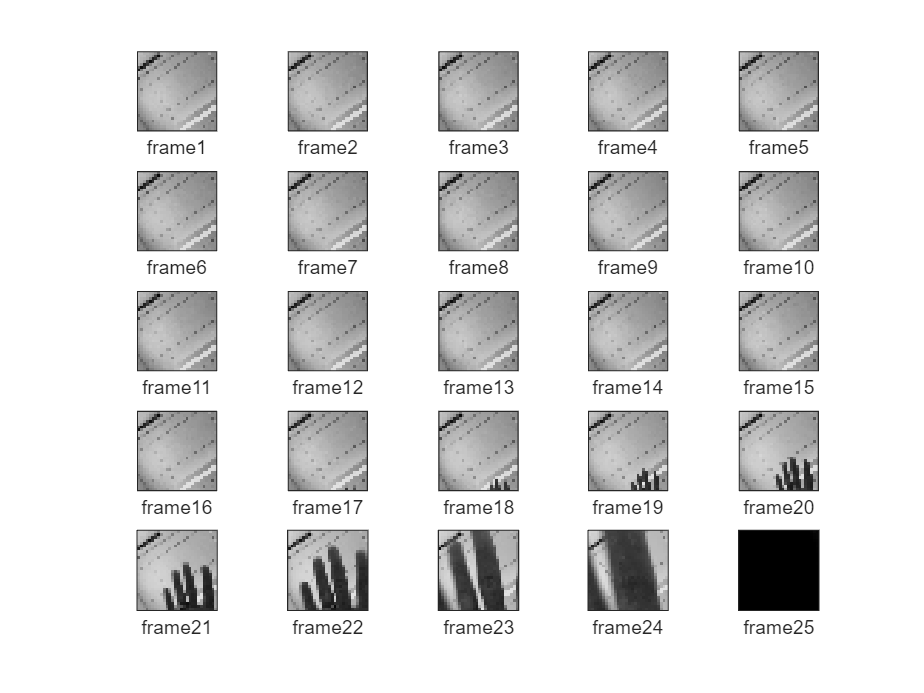

clf; % clear the display area
for f=1:25 % loop through video frames
    subplot(5,5,f); % display each frame in its own subplot
    image(255-squeeze(vid(:,:,f))); %plot the current frame
    set(gca,'XTick','','YTick',''); % no axis labels 
    axis square; % plot as perfect square
    colormap(gca,'gray'); % grayscale image
    xlabel(['frame' num2str(f)]); % label each imagewith its frame number
end

## SECTION 3: Adapting versus non-adapting photoreceptors

Sensory receptor neurons become depolarized (or hyperpolarized) in response to to sensory stimuli. For example, photoreceptors (visual sensory neurons) become hyperpolarized in response to light falling on the photoreceptor. Photoreceptors are hyperpolarized by light and depolarized by darkness.

A "non-adapting" photoreceptor starts responding when a stimulus turns on (for example, a dark shadow falls upon the photoreceptor), then continues to respond throughout the stimulus, and stops responding when the stimulus turns off (when the shadow passes by). A "slow-adapting" photoreceptor responds strongly to the onset of the stimulus, but less strongly during the remainder of the stimulus.  A "fast-adapting" photoreceptor is excited mainly at the onset of a stimulus (e.g., the appearance of a shadow) and inibited by the offset of the stimulus (disappearance of the shadow), with very little responding in between.

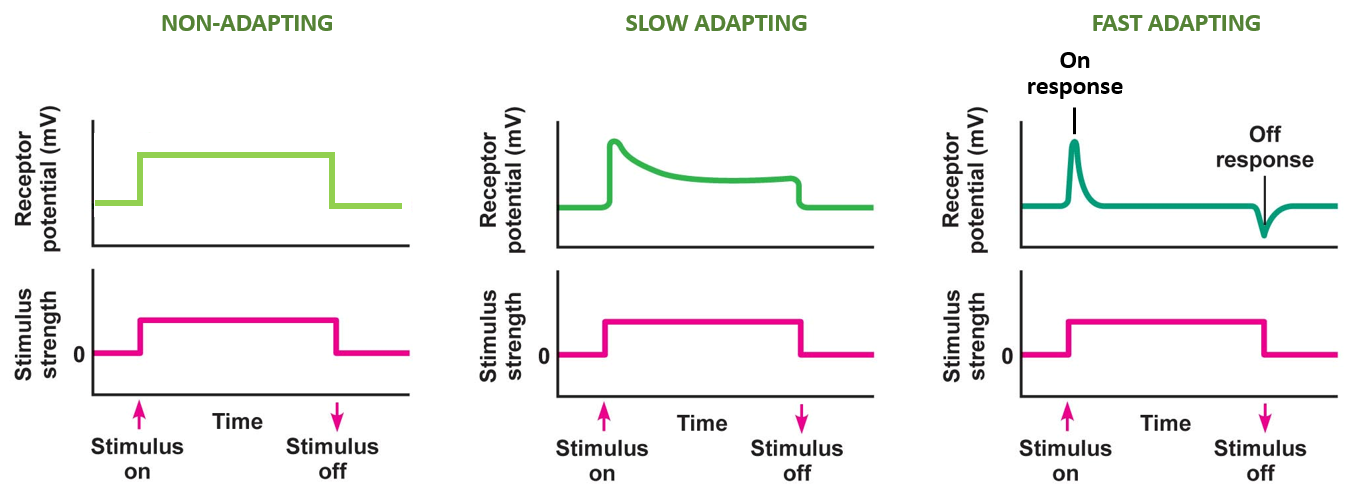 

Now, let's consider how a fly's photoreceptors would respond to the looming stimulus above. At frame 22, non-adapting and fast adapting photoreceptors would produce the following images:   

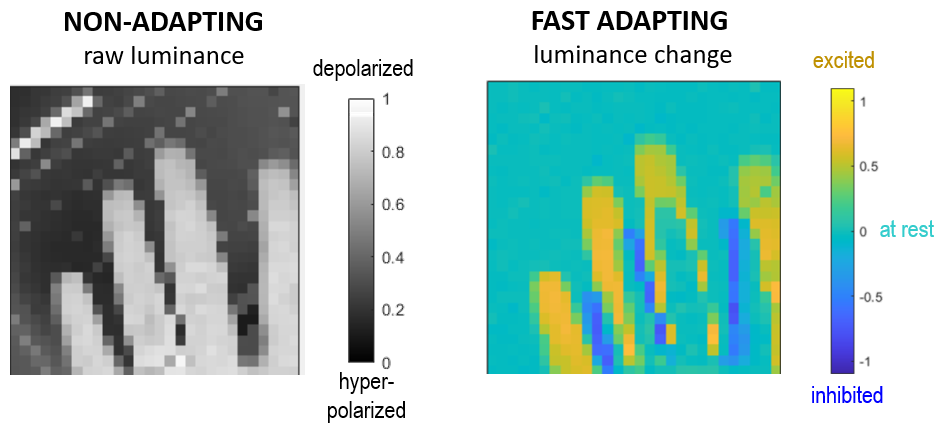

Notice that in the left image, the dark shadow of the hand is causes non-adapting photoreceptors to become depolarized, so the region of the hand appears white (indicating depolarization of photoreceptors by darkness). In the right image, fast adapting photoreceptors are excited (yellow) in regions where photoreceptors are active in the current frame (22) but were not active in the prior frame (21); conversely, fast adapting photoreceptors are inhibited (dark blue) in regions where photoreceptors were active in the prior frame (21) but are no longer active in the current frame (22).  

Run the script below (with 'Run Section') to see how fast adapting photoreceptors would respond during each image frame from the looming sequence.

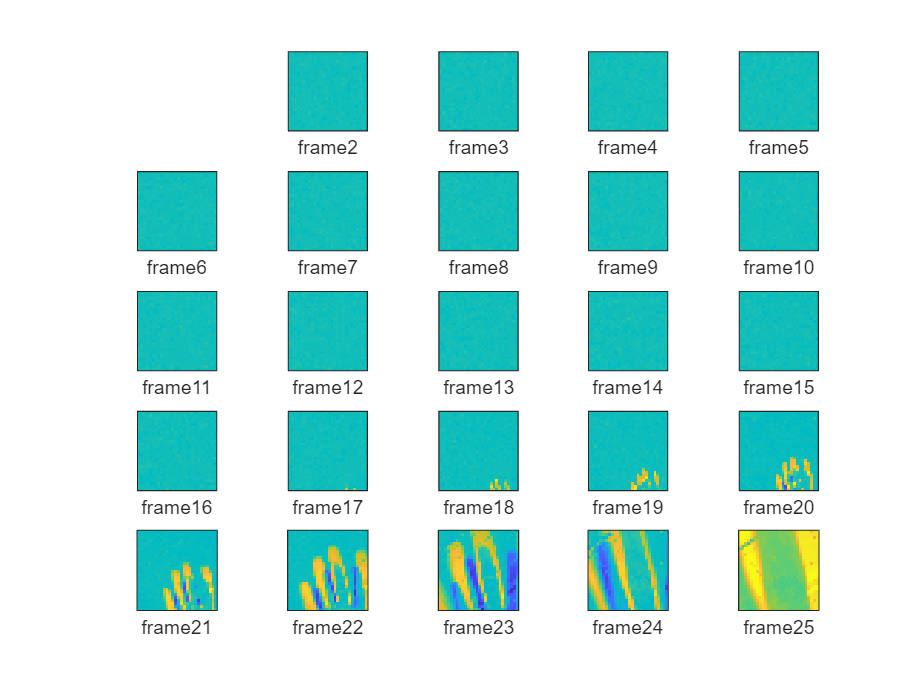

clf; % clear the display area
for f=2:25 % start loop at frame 2 since there is nothing prior to frame 1
    subplot(5,5,f); % display each frame in its own subplot
    imagesc(squeeze(vid(:,:,f)-vid(:,:,f-1))/255); % plot difference image; dividing by 255 normalizes to [-1,1]
    set(gca,'XTick','','YTick',''); % no axis labels 
    axis square; % plot as perfect square
    caxis([-.8 .8]); % set range for color axis
    colormap(gca,'parula'); % use the parula (blue/yellow) color scheme
    xlabel(['frame' num2str(f)]); % label each image with frame number
end

## SECTION 4: The Giant Axon Neuron (GAN)

This problem of discriminating danger (class 1) from safety (class 0) is solved by a single neuron in the fly's brain (well, actually two neurons--one on each side of the brain) called the GIANT AXON NEURON (GAN). The GAN receives many different types of sensory information including visual, auditory, and somatosensory signals. Here, we shall only consider visual inputs to the GAN. 

The GAN receives visual information through synaptic inputs from photoreceptors in the fly's compound eye. GAN sends output to motor neurons in the fly's body that drive muscle contractions for the jump and flight escape response. Let us suppose that the GAN neuron receives inputs from fast adapting photoreceptors:  

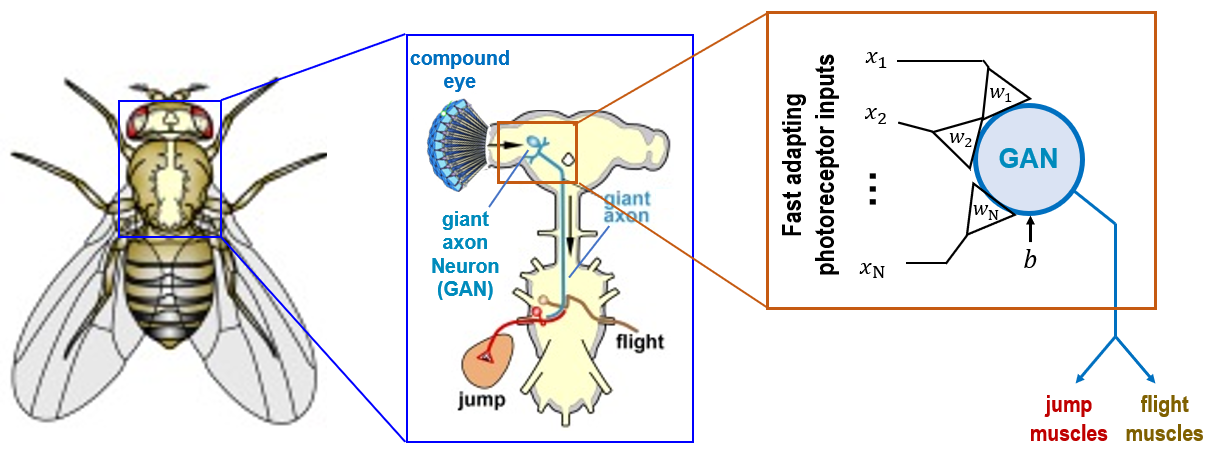

We can draw a more detailed diagram of the GAN neuron as follows:

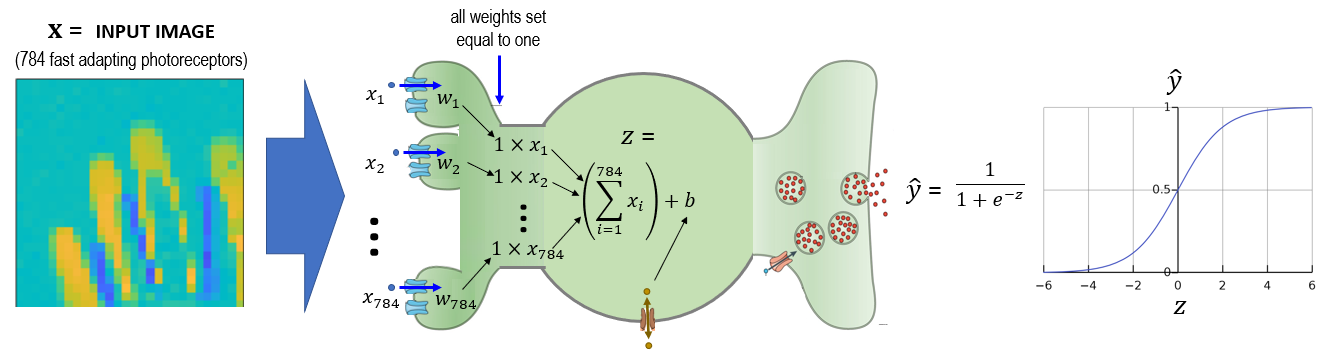

The GAN neuron receives synaptic input from 28x28=784 fast adapting photoreceptors. The value of each photo receptor input can range from x=-1 (maximally inhibited, dark blue pixels) to x=+1 (maximally excited, bright yellow pixels). For simplicity, we shall assume that the weight (or strength) of each synapse is w=1, so the GAN neuron's membrane potential z is simply the sum of all 784 photoreceptor inputs, plus the value of the bias term, b.

The output from the GAN neuron (denoted y_hat) is a sigmoid function of the membrane potential z. 

Given the information in the diagram, what are the largest and smallest possible values of z and y_hat? Enter your answers in the boxes below: 

%smallest possible value of z:
minz="-784";
%largest possible value of z:
maxz="784";
%smallest possible value of y_hat:
minyhat="0";
%largest possible value of y_hat:
maxyhat="1";

[minz maxz minyhat maxyhat] % display current answers

ans = 1×4 string array
    "-784"    "784"    "0"    "1"


## SECTION 5: Response of the GAN neuron to a looming stimulus (swatting hand)

To simulate the response of the GAN neuron to a looming stimulus, hit the 'Run Section' to execute the script below. You can set the value of the bias term (b) by editing the box at the top of the script. See if you can find a value of b that gives the following output from the GAN neuron:

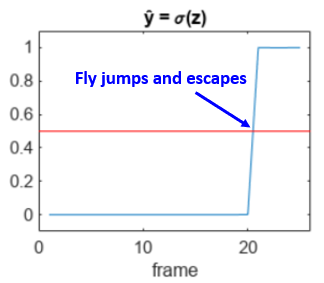

The red horizontal line at y_hat=.5 is the decision boundary. The fly will execute the jump escape reflex at the first moment when y_hat goes above the red line. 

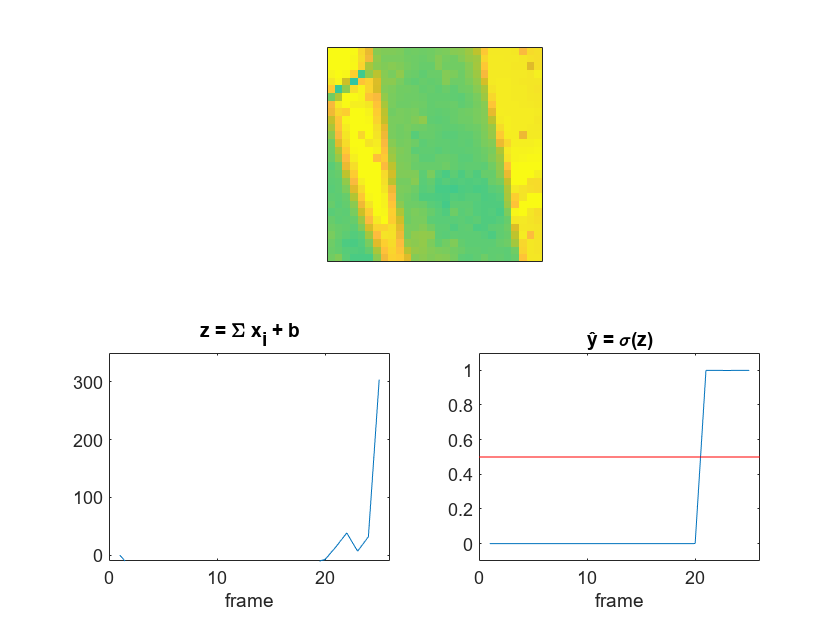

b=-20; % set value of bias term

clf; % clear the display area
subplot(2,2,[1 2]); % video frame will plot in top half of a 2x2 subplot matrix
hImg = imagesc(squeeze(vid(:,:,2)-vid(:,:,1))/255); % plot difference image, set image plot handle
set(gca,'XTick','','YTick',''); % no axis labels 
axis square; % plot as perfect square
caxis([-.8 .8]); % set range for color axis
colormap(gca,'parula'); % use the parula (blue/yellow) color scheme

% initialize z plot with null data and define axis limits
subplot(2,2,3); % z value graph displays in lower left subplot
zPlot = plot(1:25,[1:25]*NaN); % display a blank graph
zPlot.YData = [0 NaN(1,24)]; % fill YData with NaNs
set(gca,'XLim',[0 26],'YLim',[-10 350]); % axis limits
xlabel('frame'); title('z = \Sigma x_{i} + b'); 

% initialize y plot with null data and define axis limits
subplot(2,2,4); % z value graph displays in lower right subplot 
yhatPlot = plot(1:25,[1:25]*NaN); % display a blank graph
yhatPlot.YData = [0 NaN(1,24)]; % fill YData with NaNs
hold on; % need to display threshold line on top of data
plot(0:26,[0:26]*0+.5,'r'); % display the red threshold line
set(gca,'XLim',[0 26],'YLim',[-.1 1.1]); % axis limits
xlabel('frame'); title([char(375) ' = \sigma(z)']);

for f=2:25 % start loop at frame 2 since there is nothing prir to frame 1
    hImg.CData=(squeeze(vid(:,:,f)-vid(:,:,f-1))/255); % copy next frame into image data 
    zPlot.YData(f)=b+sum(sum(vid(:,:,f)-vid(:,:,f-1)))/255; % copy next z into plot data 
    yhatPlot.YData(f)=1/(1+exp(-zPlot.YData(f))); % copy next y into plot data 
    drawnow limitrate; % render image before the next loop iteration
    pause(.1); % pause to slow down the frame rate
end

## SECTION 6: Response of the GAN Neuron to a non-looming stimulus (passing hand)

It is important for the GAN neuron to fire when danger is present, but it is also important for the GAN neuron not fire when danger is not present. Otherwise, the fly will constantly be over reacting to any small stimulus in its environment. 

The script below simulates the response of the GAN neuron to a hand that is waving in the distance, but not coming closer to the fly (and thus not posing a threat). Again, you can set the value of the bias term (b) by editing the box at the top of the script. See if you can find a value of b that gives the following output from the GAN neuron:      

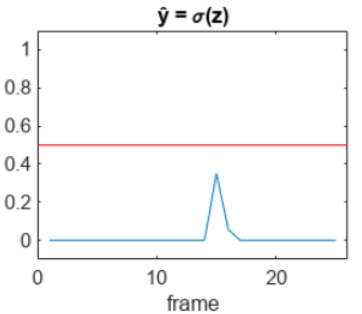

Notice that since y_hat does not go above the red line, the fly does not respond to the stimulus.

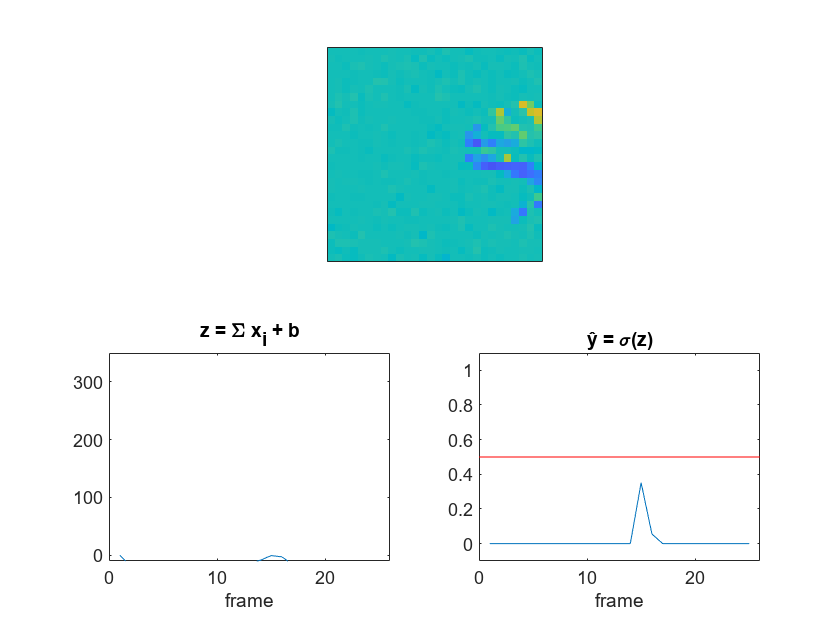

b=-18; % set value of bias term

clf; % clear the display area
subplot(2,2,[1 2]); % video frame will plot in top half of a 2x2 subplot matrix
hImg = imagesc(squeeze(vid2(:,:,2)-vid2(:,:,1))/255); % plot difference image, set image plot handle
set(gca,'XTick','','YTick',''); % no axis labels 
axis square; % plot as perfect square
caxis([-.8 .8]); % set range for color axis
colormap(gca,'parula'); % use the parula (blue/yellow) color scheme

% initialize z plot with null data and define axis limits
subplot(2,2,3); % z value graph displays in lower left subplot
zPlot = plot(1:25,[1:25]*NaN); % display a blank graph
zPlot.YData = [0 NaN(1,24)]; % fill YData with NaNs
set(gca,'XLim',[0 26],'YLim',[-10 350]); % axis limits
xlabel('frame'); title('z = \Sigma x_{i} + b'); 

% initialize y plot with null data and define axis limits
subplot(2,2,4); % z value graph displays in lower right subplot 
yhatPlot = plot(1:25,[1:25]*NaN); % display a blank graph
yhatPlot.YData = [0 NaN(1,24)]; % fill YData with NaNs
hold on; % need to display threshold line on top of data
plot(0:26,[0:26]*0+.5,'r'); % display the red threshold line
set(gca,'XLim',[0 26],'YLim',[-.1 1.1]); % axis limits
xlabel('frame'); title([char(375) ' = \sigma(z)']);

for f=2:25 % start loop at frame 2 since there is nothing prir to frame 1
    hImg.CData=(squeeze(vid2(:,:,f)-vid2(:,:,f-1))/255); % copy next frame into image data 
    zPlot.YData(f)=b+sum(sum(vid2(:,:,f)-vid2(:,:,f-1)))/255; % copy next z into plot data 
    yhatPlot.YData(f)=1/(1+exp(-zPlot.YData(f))); % copy next y into plot data 
    drawnow limitrate; % render image before the next loop iteration
    pause(.1); % pause to slow down the frame rate
end

## SECTION 7: Setting the decision boundary by adjusting the bias term

To properly discriminate safety from danger, we need to set the decision boundary in the proper place. Normally, we would adjust the decision boundary through a lewrning process to adjust the model's weight (w) and bias (b) parameters. But the GAN neurons represents a rather special case where we can set all weights to the same value (for eaxmple, w=1), and then adjust the decision boundary only by changing the bias parameter, b.

To see why this works, consider the following examples of fast adapting photoreceptor activity in response to a passing hand versus a swatting hand:  

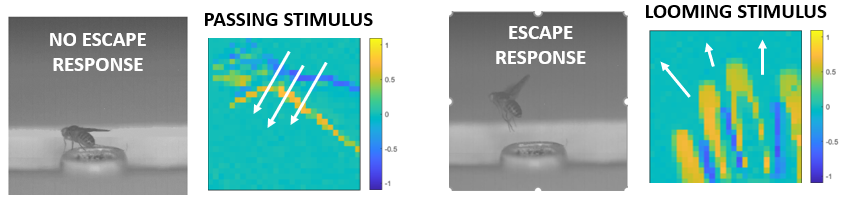

The passing hand is moving downward (white arrows) so photoreceptors at the hand's leading edge are excited (yellow) and photoreceptors at the trailing edge are inhibited (dark blue). The excited (positive x values) and inhibited (negative x values) photoreceptors are about equal in number. Assuming equal weights for every synapse, the sum of all photoreceptor outputs would be near z=0 because positive and negative x values would cancel out.. 

The looming hand is moving toward the fly, so visual motion is radially outward from the center of the approaching hand. Consequently, all of the hand's edges are leading edges, and none are trailing edges. There are more excited (yellow) photoreceptors than inhibited (dark blue) photoreceptors. The positive x values outnumber the negative x values. Assuming equal weight values, the sum will tend to be a positive number, z>0. 

So, we can see that under the assumption of equal weight values, a passing stimulus will give z=0 and a looming stimulus will give z>0. Thus, we can set all the weights to the same value, and then set b to determine how large z needs to get before it triggers the escape response:   

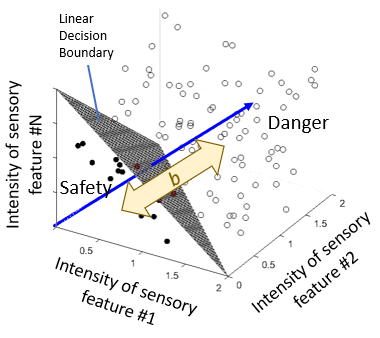

The only reason this 'bias adjustment' method works for the escape response is because the GAN neuron can set a simple intensity threshold to classify 'safety' versus 'danger.' If the danger level depended on more compex features of the stimulus (such as whether the approaching stimulus moves left vs right, whether it is another fly versus a different species, etc.), rather than just its intensity, then we would need to fine tune the weights to make the GAN neuron selectively sensitive to those specific stimulus features that signal danger.

In the simulation below, all weights are set to a single value that depends upon your student ID number (hence, the value of the weights will be different for each student in the class). 

Your task is to enter a value for b_best in the box that is the LARGEST INTEGER VALUE FOR b WHICH DISCIMRINATES SAFETY FROM DANGER (THAT IS, THE LARGEST VALUE FOR WHICH A LOOMING STIMULUS ELICITS AN ESCAPE RESPONSE, AND A PASSING STIMULUS DOES NOT). 

Note: the correct answer will be different for each student.

Adjust the value of b_best and hit 'Run Section' until you find the correct answer. You should only enter INTEGER NUMBERS (no decimal point). 

When you have found the largest (least negative, if the number is negative) value for b_best that discriminates safety from danger, proceed to the next section.  

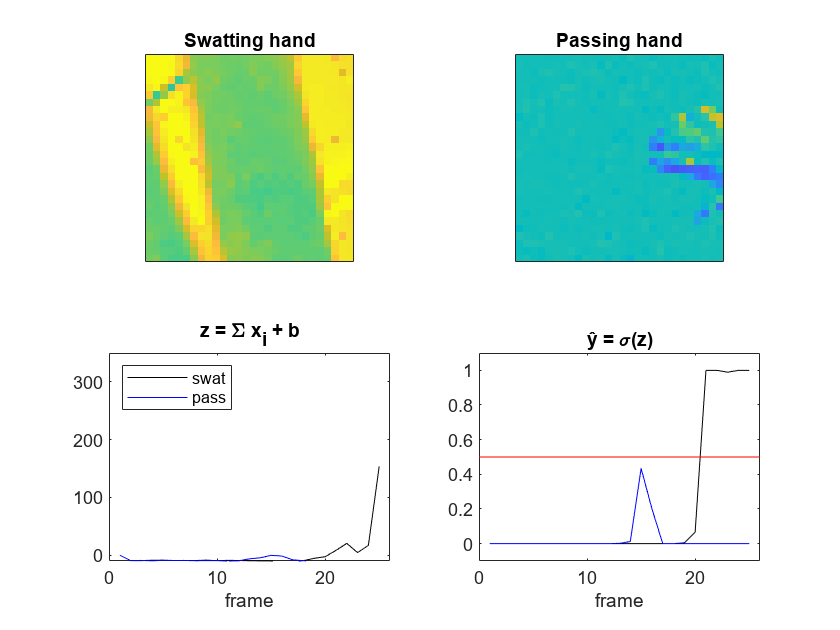

b_best=-9; % set value of bias term

run([workingfolder '/SIDfile']); % user ID file
W=.5+rand()/2; %set all weights to a value that depends student's ID number

clf; % clear the display area

subplot(2,2,1); % swatting hand video will plot in top left of 2x2 subplot matrix
hImg_swat = imagesc(squeeze(vid(:,:,2)-vid(:,:,1))/255); % plot difference image, set image plot handle
set(gca,'XTick','','YTick',''); % no axis labels 
axis square; % plot as perfect square
caxis([-.8 .8]); % set range for color axis
colormap(gca,'parula'); % use the parula (blue/yellow) color scheme
title('Swatting hand');

subplot(2,2,2); % passing hand video will plot in top right of 2x2 subplot matrix
hImg_pass = imagesc(squeeze(vid2(:,:,2)-vid2(:,:,1))/255); % plot difference image, set image plot handle
set(gca,'XTick','','YTick',''); % no axis labels 
axis square; % plot as perfect square
caxis([-.8 .8]); % set range for color axis
colormap(gca,'parula'); % use the parula (blue/yellow) color scheme
title('Passing hand');

% initialize z plot with null data and define axis limits
subplot(2,2,3); % z value graph displays in lower left subplot
zPlot_swat = plot(1:25,[1:25]*NaN,'k'); % swatting hand output displays in black
zPlot_swat.YData = [0 NaN(1,24)]; % fill YData with NaNs
hold on;
zPlot_pass = plot(1:25,[1:25]*NaN,'b'); % passing hand output displays in blue
zPlot_pass.YData = [0 NaN(1,24)]; % fill YData with NaNs
set(gca,'XLim',[0 26],'YLim',[-10 350]); % axis limits
xlabel('frame'); title('z = \Sigma x_{i} + b'); 
legend('swat', 'pass','Location','northwest');

% initialize y plot with null data and define axis limits
subplot(2,2,4); % z value graph displays in lower right subplot 
yhatPlot_swat = plot(1:25,[1:25]*NaN,'k');  % swatting hand output displays in black
yhatPlot_swat.YData = [0 NaN(1,24)]; % fill YData with NaNs
hold on; % need to display threshold line on top of data
yhatPlot_pass = plot(1:25,[1:25]*NaN,'b');  % passing hand output displays in blue
yhatPlot_pass.YData = [0 NaN(1,24)]; % fill YData with NaNs
plot(0:26,[0:26]*0+.5,'r'); % display the red threshold line
set(gca,'XLim',[0 26],'YLim',[-.1 1.1]); % axis limits
xlabel('frame'); title([char(375) ' = \sigma(z)']);

for f=2:25 % start loop at frame 2 since there is nothing prior to frame 1
    hImg_swat.CData=(squeeze(vid(:,:,f)-vid(:,:,f-1))/255); % copy next frame into image data 
    hImg_pass.CData=(squeeze(vid2(:,:,f)-vid2(:,:,f-1))/255); % copy next frame into image data 
    zPlot_swat.YData(f)=b_best+W*sum(sum(vid(:,:,f)-vid(:,:,f-1)))/255; % copy next z into plot data 
    zPlot_pass.YData(f)=b_best+W*sum(sum(vid2(:,:,f)-vid2(:,:,f-1)))/255; % copy next z into plot data 
    yhatPlot_swat.YData(f)=1/(1+exp(-zPlot_swat.YData(f))); % copy next y into plot data 
    yhatPlot_pass.YData(f)=1/(1+exp(-zPlot_pass.YData(f))); % copy next y into plot data 
    drawnow limitrate; % render image before the next loop iteration
    pause(.1); % pause to slow down the frame rate
end

## SECTION 8: You are done! Submit your work to Canvas

To submit your assignment, follow three steps:

1) run the script below by clicking inside the code window and then hitting 'Run Section' (three graphs will appear below the code)

2) a file called '123456789_assignment2.png' will be created in your 119D directory (with your SID in place of 123456789)

3) upload this file to Canvas to submit your completed assignment!

% SAVE FILE TO SUBMIT ON CANVAS

answer.minz=minz;
answer.maxz=maxz;
answer.minyhat=minyhat;
answer.maxyhat=maxyhat;
answer.b_best=b_best;
filename = [num2str(SID) '_assignment2.mat'];
save([workingfolder '/' filename],'answer');